% ejercicio3_circular.m
clear; close all; clc;

%% Parámetros y tiempo
r    = 0.1;     % radio de rueda [m]
L    = 0.4;     % separación ejes [m]
R    = 20;      % radio de la circunferencia [m]
v    = 1.0;     % velocidad lineal deseada [m/s]
omega_c = v/R;  % velocidad angular del cuerpo [rad/s]
dt   = 1;       % paso de muestreo [s]
t    = 0:dt:2*pi*R/v;  % tiempo para una vuelta completa
N    = length(t);

%% Cálculo de ω_R y ω_L constantes
omega_R = (v/r) + (L*omega_c)/(2*r);
omega_L = (v/r) - (L*omega_c)/(2*r);
wR = omega_R * ones(N,1);
wL = omega_L * ones(N,1);

%% Cinemática directa
v_vec = v * ones(N,1);
w_vec = omega_c * ones(N,1);

%% Integración Euler (arranca en (R,0) mirando +Y)
x = zeros(N,1); 
y = zeros(N,1);
phi = zeros(N,1);
x(1)   = R;
y(1)   = 0;
phi(1) = pi/2;
for k = 1:N-1
    phi(k+1) = phi(k) + w_vec(k)*dt;
    x(k+1)   = x(k)   + v_vec(k)*cos(phi(k))*dt;
    y(k+1)   = y(k)   + v_vec(k)*sin(phi(k))*dt;
end

%% Tabla de resultados
T3 = table( ...
  t', wR, wL, x, y, rad2deg(phi), ...
  'VariableNames', ...
  {'t_s','omega_R','omega_L','x_m','y_m','theta_deg'});
disp(T3);

    t_s    omega_R    omega_L       x_m         y_m       theta_deg
    ___    _______    _______    _________    ________    _________

      0     10.1        9.9             20           0         90  
      1     10.1        9.9             20           1     92.865  
      2     10.1        9.9          19.95      1.9988      95.73  
      3     10.1        9.9          19.85      2.9938     98.594  
      4     10.1        9.9         19.701      3.9825     101.46  
      5     10.1        9.9         19.502      4.9626     104.32  
      6     10.1        9.9         19.255      5.9315     107.19  
      7     10.1        9.9         18.959      6.8868     110.05  
      8     10.1        9.9         18.616      7.8262     112.92  
      9     10.1        9.9         18.227     

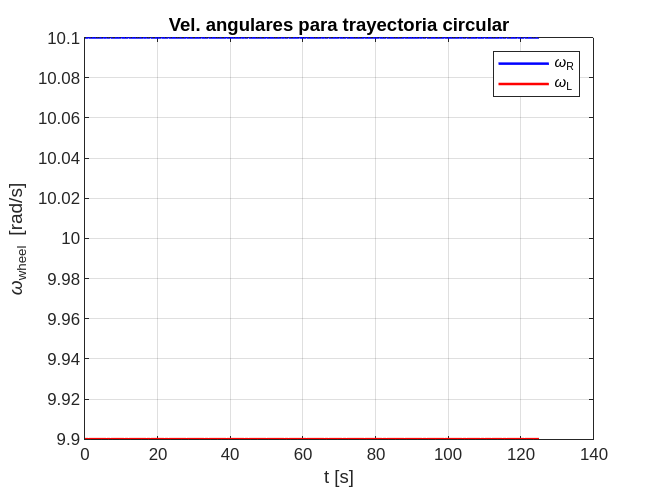


%% Gráfica ω_R y ω_L
figure;
plot(t, wR,'b-', t, wL,'r-','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega_{wheel} [rad/s]')
legend('\omega_R','\omega_L'), title('Vel. angulares para trayectoria circular')

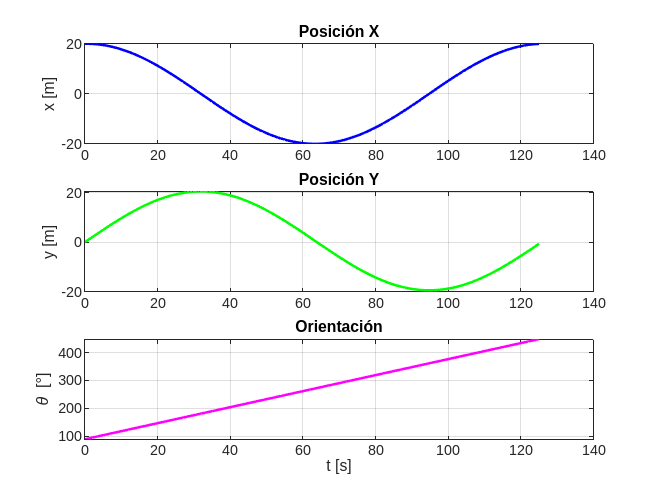


%% Gráficas de pose
figure;
subplot(3,1,1)
plot(t, x,'b-','LineWidth',1.5), grid on, ylabel('x [m]'), title('Posición X')
subplot(3,1,2)
plot(t, y,'g-','LineWidth',1.5), grid on, ylabel('y [m]'), title('Posición Y')
subplot(3,1,3)
plot(t, rad2deg(phi),'m-','LineWidth',1.5), grid on,
xlabel('t [s]'), ylabel('\theta [°]'), title('Orientación')

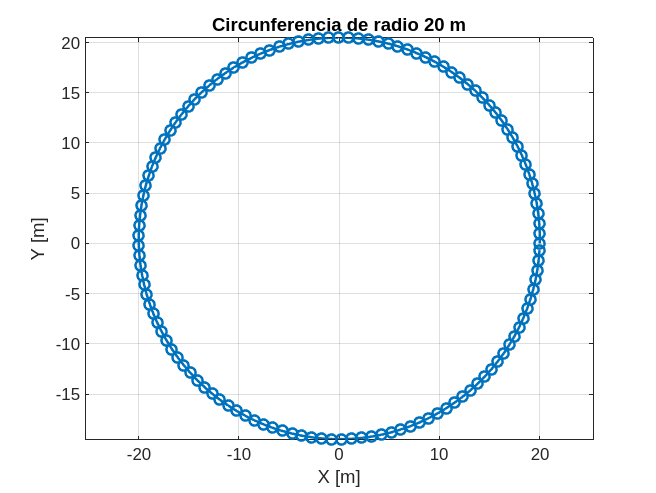


%% Trayectoria estática XY
figure;
plot(x, y,'-o','LineWidth',1.5), axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]'), title('Circunferencia de radio 20 m')

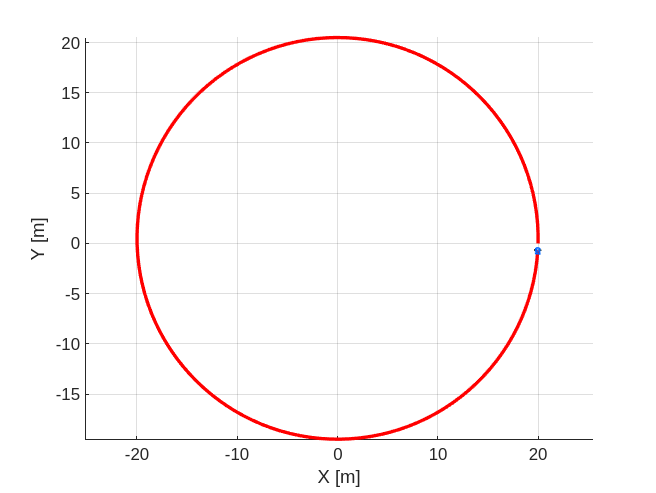


%% Animación 2D
figure; axis equal; grid on; hold on
xlabel('X [m]'), ylabel('Y [m]'), view(2)
MobileRobot_5; scale=4;
hR = MobilePlot_4(x(1), y(1), phi(1), scale);
hT = plot(x(1), y(1), 'r-','LineWidth',2);
for k = 2:N
    delete(hR); delete(hT)
    hR = MobilePlot_4(x(k), y(k), phi(k), scale);
    hT = plot(x(1:k), y(1:k), 'r-','LineWidth',2);
    pause(dt)
end